# Audio Signal Recovery from Sparse Measurements


$$x\left(t\right)=\cos \left(2\pi 97t\right)+\cos \left(\left(2\pi 777t\right)\right)$$


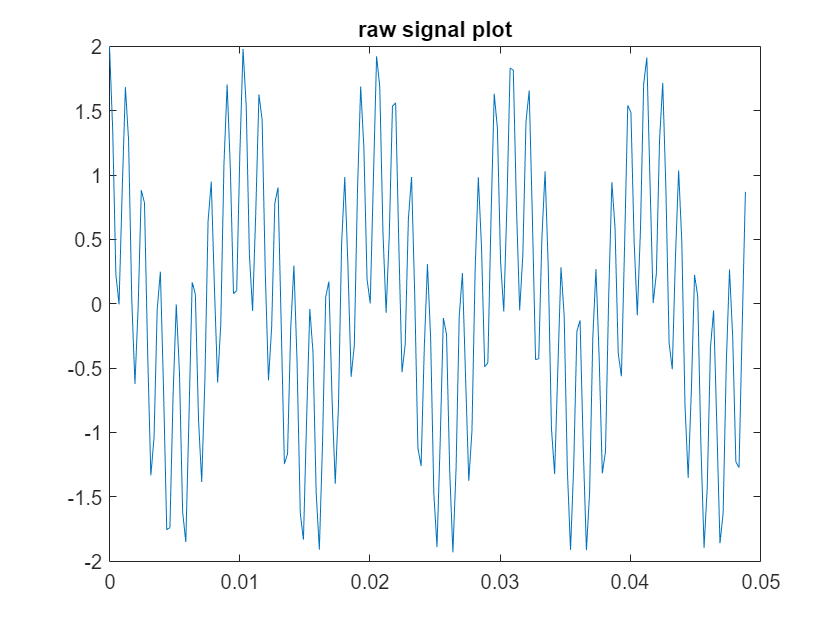

n = 4096;

t = linspace(0,1,n);
x = cos(2*pi*97*t) + cos(2*pi*777*t);

plot(t(1:201),x(1:201))
title("raw signal plot")

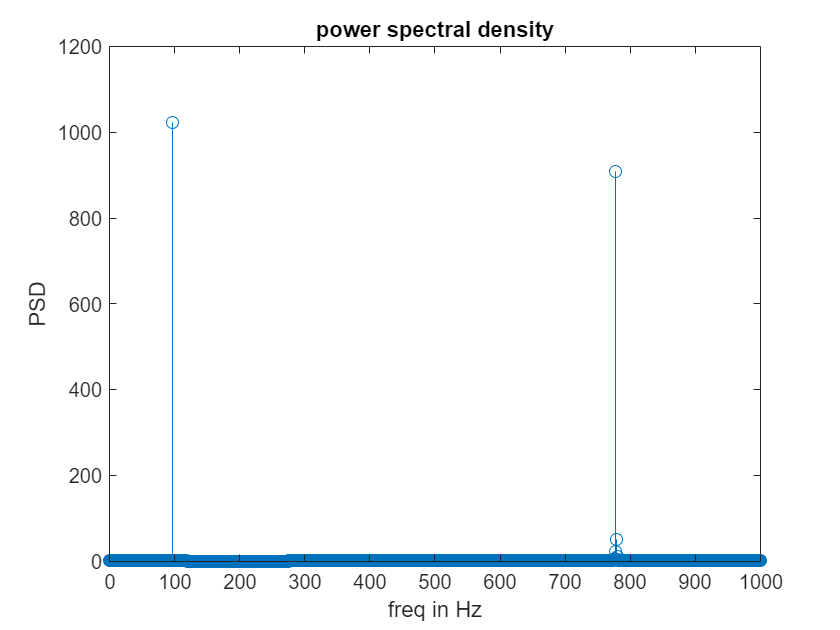

xt = fftshift(fft(x));
PSD = xt.*conj(xt)/n;
fs = 4096;
freq = linspace(-n/2,n/2,4096);
stem(freq(n/2:end), PSD(n/2:end))
title("power spectral density")
xlim([0 1000])
xticks(linspace(0,1000,11))
xlabel('freq in Hz')
ylabel('PSD')

p = 128;
meas = round(rand(p, 1) * n);
y = x(meas); % compressed measurement

Psi = dct(eye(n, n)); % build Psi
Theta = Psi(meas, :); % Measure rows of Psi

cvx_begin;
    variable s(n);
    minimize( norm(s,1) );
    subject to
        Theta*s == y';
cvx_end;

 
Calling SDPT3 4.0: 8192 variables, 124 equality constraints
------------------------------------------------------------

 num. of constraints = 124
 dim. of socp   var  = 8192,   num. of socp blk  = 4096
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|9.1e-01|6.3e+01|5.6e+05| 8.571939e+03  0.000000e+00| 0:0:00| chol  2  2 
 1|1.000|0.958|1.1e-08|2.7e+00|3.5e+04| 9.411895e+03  9.649735e+01| 0:0:01| chol  1  1 
 2|1.000|1.000|1.3e-08|9.8e-03|5.1e+03| 5.107697e+03  7.691825e+01| 0:0:01| chol  1  1 
 3|0.807|0.283|3.1e-08|7.3e-03|1.6e+03| 1.653669e+03  1.000867e+02| 0:0:02| chol  1  1 
 4|0.649|0.224|2.2e-08|5.7e-03

xrecon = idct(s); % reconstruct full signal
xreconfft = fftshift(fft(xrecon));
PSD_xrecon = xreconfft.*conj(xreconfft)/n;

# Compare power spectral densities

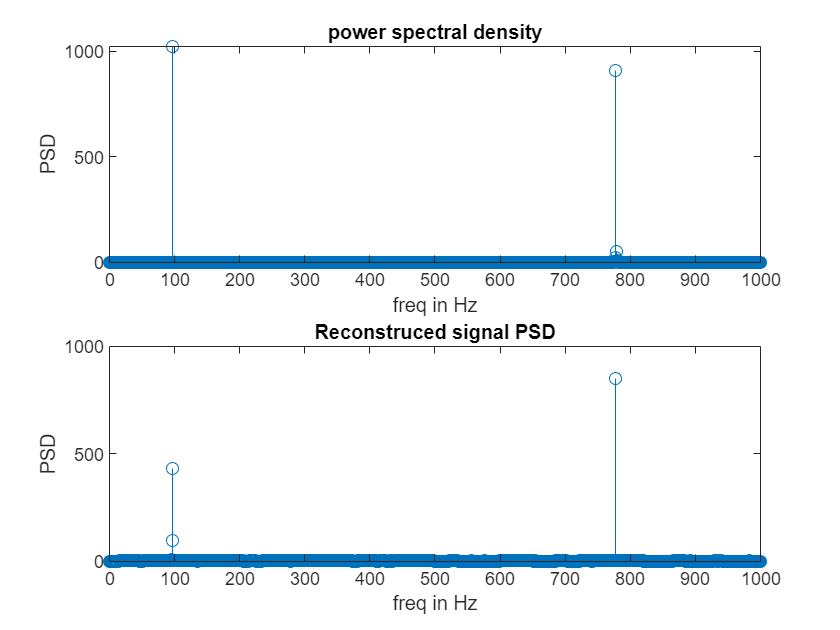

subplot(211)
freq = linspace(-n/2,n/2,4096);
stem(freq(n/2:end), PSD(n/2:end))
title("power spectral density")
xlim([0 1000])
xticks(linspace(0,1000,11))
xlabel('freq in Hz')
ylabel('PSD')


subplot(212)
freq = linspace(-n/2,n/2,4096);
stem(freq(n/2:end), PSD_xrecon(n/2:end))
title("Reconstruced signal PSD")
xlim([0 1000])
xticks(linspace(0,1000,11))
xlabel('freq in Hz')
ylabel('PSD')

# Compare the plots

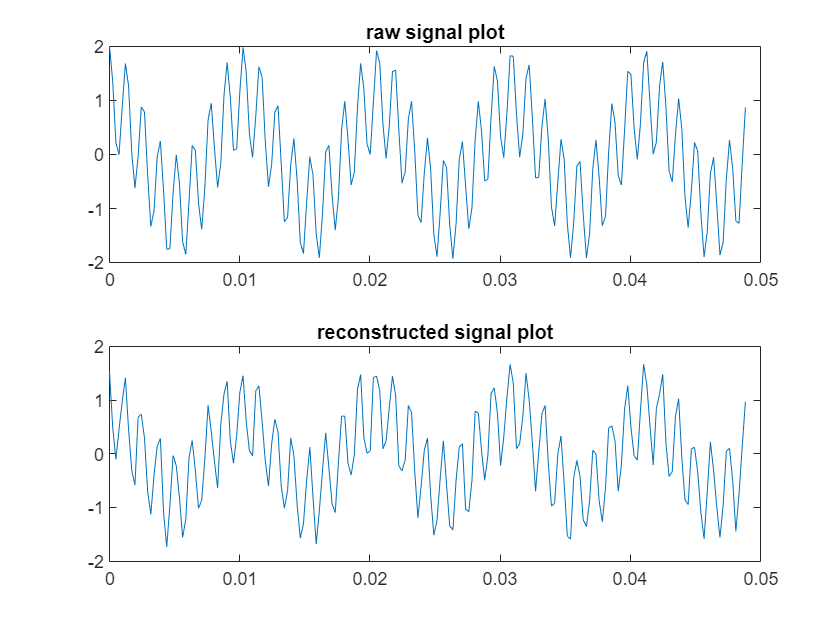

subplot(211)
plot(t(1:201),x(1:201))
title("raw signal plot")

subplot(212)
plot(t(1:201),xrecon(1:201))
title("reconstructed signal plot")